# Návrh regulátoru metodou tvarování frekvenčních charakteristik

## Vymazání proměnných z workspace, získání parametrů soustavy pro model

clc;
close all;
clearvars;
ID  = 256421;
[A, D, g, rho, J, B, ke, R, L, C, Fs, Fv] = gen_sys2025(ID);


Fs =
 
            5.7621e+11
  ------------------------------
  (s+694.2)^2 (s+19.1) (s+3.732)
 
Continuous-time zero/pole/gain model.
Model Properties

Fv =
 
  -1551.4 (s+1190) (s+220.4) (s+0.7153)
  -------------------------------------
     (s+694.2)^2 (s+19.1) (s+3.732)
 
Continuous-time zero/pole/gain model.


## Načtení regulátorů ze souboru Control System Designer

load("FCHAR.mat");
tunedDesigns = ControlSystemDesignerSession.DesignerData.Designs;
PI = tunedDesigns(2).Data.C;
PID_10 = tunedDesigns(1).Data.C;
PID_100 = tunedDesigns(3).Data.C;

# Návrh PI regulátoru

## Získání Kp a Ti

[Kp, Ti,~,~]=pidstddata(PI)

Kp = 1.8646e-04

Ti = 0.2680

## Inicializace řídicího signálu, inicializace poruchy

t = 0:1e-4:4;
iz_data = 0.02* (t > 0.5);
iz = timeseries(iz_data, t);
ug_data = 5*ones(size(t));
ug = timeseries(ug_data, t);

## Spuštění simulace

out_pi = sim("FCHARmodPI.slx");

## Vykreslení získaných charakteristik

figure;
title(tiledlayout(3,2,"TileSpacing","loose"), "Charakteristiky přenosu pro PI regulátor navržený tvarováním frekv. charakteristik");
nexttile;

- Vstupní objemový průtok

p = plot(out_pi.Qin.Time, out_pi.Qin.Data);
grid on;
title('Q_{in} (t)');

Q_ss = 0.308;
yline(Q_ss,'--k',sprintf('Q_{in} = %.f ml/s',Q_ss*1000),'LineWidth',1.3);

xregion(0.5,0.8,'FaceColor', "r");
xlabel('t [s]');
ylabel('Q_{in} [dm^3\cdot s^{-1}]');

- Výška hladiny

nexttile;
plot(out_pi.h.Time, out_pi.h.Data);
h2 = 34;
yline(34,'--r',sprintf('\\omega_2 = %.f cm', h2),'LineWidth',0.7);
xregion(0.5,4,'FaceColor', "y");
grid on;
title('h(t)');
ylim([0 50]);
yticks([0,20,40,60])
xlabel('t [s]');
ylabel('h [cm]');

- Regulační odchylka

nexttile;
plot(out_pi.e.Time, out_pi.e.Data);
xregion(0.5,0.8,'FaceColor', "r");
grid on;
title('e(t)');
xlabel('t [s]');
ylabel('e [V]');

- Proud tekoucí kotvou DC generátoru

nexttile;
plot(out_pi.i.Time, out_pi.i.Data);
i2 = 20;
yline(i2,'--r',sprintf('i_2 = i_z = %.f mA', i2),'LineWidth',0.7);
xregion(0.5,4,'FaceColor', "y");
grid on;
ylim([0 30]);
title('i(t)');
xlabel('t [s]');
ylabel('i [mA]');

- Napětí na výstupu hydrogenerátoru

nexttile;
plot(out_pi.ug.Time, out_pi.ug.Data);
xregion(0.5,0.8,'FaceColor', "r");
grid on;
title('U_g(t)');
xlabel('t [s]');
ylabel('u_g [V]');

- Úhlová rychlost DC generátoru

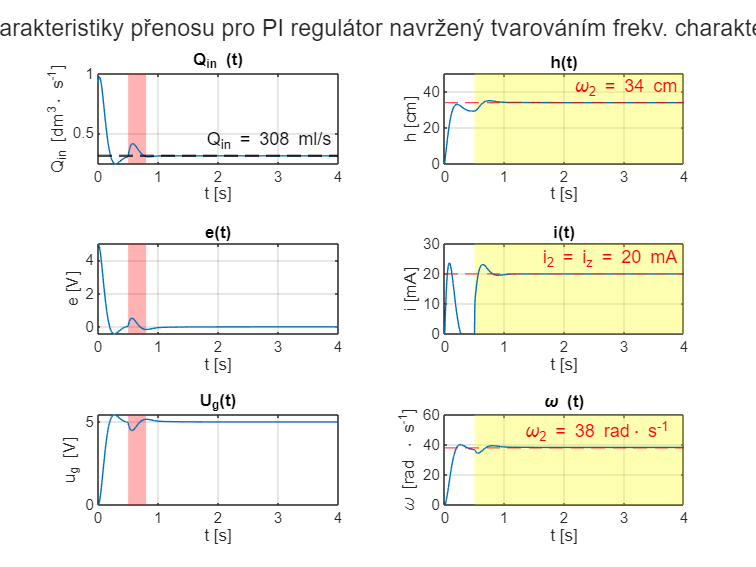

nexttile;
plot(out_pi.w.Time, out_pi.w.Data);
xregion(0.5,4,'FaceColor', "y");
w2 = 38;
yline(w2,'--r',sprintf('\\omega_2 = %.f rad\\cdot s^{-1} ', w2),'LineWidth',0.7);
grid on;
title('\omega (t)');
ylim([0 60]);
yticks([0,20,40,60])
xlabel('t [s]');
ylabel('\omega [rad \cdot s^{-1}]');

### Export naměřených charakteristik do nového .pdf souboru

if isfile("FCHARPI.pdf")
    delete("FCHARPI.pdf");
end
exportgraphics(gcf, 'FCHARPI.pdf', 'ContentType', 'vector');

# Návrh PID regulátoru s realizační časovou konstantou N = 10

## Získání Kp, Ti, Td, N

[Kp, Ti, Td, N] = pidstddata(PID_10)

Kp = 0.0015

Ti = 0.3163

Td = 0.0403

N = 10.0000

t = 0:1e-4:4;
iz_data = 0.02* (t > 0.4);
iz = timeseries(iz_data, t);
out_pid = sim("FCHARmodPID.slx");

## Vykreslení získaných charakteristik

figure;
title(tiledlayout(3,2,"TileSpacing","loose"), "Charakteristiky přenosu pro PID regulátor s realizační časovou konstantou N = 10");

- Objemový průtok

nexttile;
plot(out_pid.Qin.Time, out_pid.Qin.Data);
Qss = 0.298;
yline(Qss,'--k',sprintf('Q_{in} = %.f ml/s',Qss*1000),'LineWidth',1.3);
grid on;
title('Q_{in} (t)');
xlim([0 0.8]);
xregion(0.4,0.44,'FaceColor', "r");
xlabel('t [s]');
ylabel('Q_{in} [dm^3\cdot s^{-1}]');

- Výška hladiny [cm]

nexttile;
plot(out_pid.h.Time, out_pid.h.Data);
yline(34,'--r',sprintf('h = %.f cm, \\Delta h = %.f cm',34, 34-29),'LineWidth',1.3);
xregion(0.4,4,'FaceColor', "y");
grid on;
title('h(t)');
xlabel('t [s]');
ylabel('h [cm]');
xlim([0 0.8]);

- Regulační odchylka [V]

nexttile;
plot(out_pid.e.Time, out_pid.e.Data);
xregion(0.4,0.45,'FaceColor', "r");
grid on;
title('e(t)');
xlabel('t [s]');
ylabel('e [V]');
xlim([0 0.8]);

- Proud tekoucí kotvou hydrogenerátoru

nexttile;
plot(out_pid.i.Time, out_pid.i.Data);
i = 20;
yline(i,'--r',sprintf('i = %.f mA',i),'LineWidth',1.3);
xregion(0.4,4,'FaceColor', "y");
grid on;
title('i(t)');
xlabel('t [s]');
ylabel('i [mA]');
xlim([0 0.8]);

- Průběh napětí [V]

nexttile;
plot(out_pid.ug.Time, out_pid.ug.Data);
grid on;
xregion(0.4,0.45,'FaceColor', "r");
title('U_g(t)');
xlabel('t [s]');
ylabel('u_g [V]');
xlim([0 0.8]);

- Průběh úhlové rychlosti

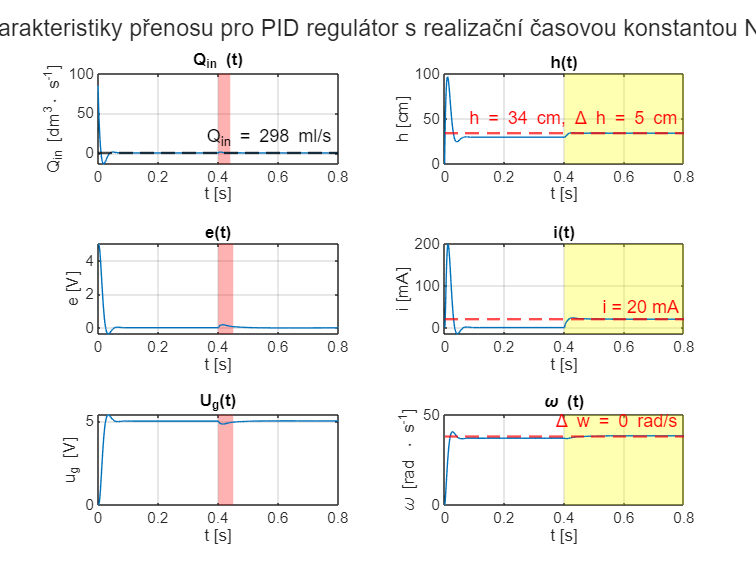

nexttile;
plot(out_pid.w.Time, out_pid.w.Data);
grid on;
xregion(0.4,4,'FaceColor', "y");
title('\omega (t)');
xlabel('t [s]');
xlim([0 0.8]);
yline(38,'--r',sprintf('\\Delta w = 0 rad/s',38),'LineWidth',1.3);
ylabel('\omega [rad \cdot s^{-1}]');

### Export naměřených charakteristik do nového .pdf souboru

if isfile("FCHARPID10.pdf")
    delete("FCHARPID10.pdf");
end

exportgraphics(gcf, 'FCHARPID10.pdf', 'ContentType', 'vector');

# Návrh PID regulátoru s realizační časovou konstantou N = 100

## Získání Kp, Ti, Td, N

[Kp, Ti, Td, N] = pidstddata(PID_100);
out_pid = sim("FCHARmodPID.slx");

## Vykreslení získaných charakteristik

figure;
title(tiledlayout(3,2,"TileSpacing","loose"), "Charakteristiky přenosu pro PID regulátor s realizační časovou konstantou N = 10");

- Objemový průtok (akční zásah)

nexttile;
plot(out_pid.Qin.Time, out_pid.Qin.Data);
xregion(0.4,0.45,'FaceColor', "r");
Qss = 0.298;
yline(Qss,'--k',sprintf('Q_{in} = %.f ml/s',Qss*1000),'LineWidth',1.3);
grid on;
title('Q_{in} (t)');
xlabel('t [s]');
xlim([0 0.9]);
ylabel('Q_{in} [dm^3\cdot s^{-1}]');

- Výška hladiny

nexttile;
plot(out_pid.h.Time, out_pid.h.Data);
yline(34,'--r',sprintf('\\Delta h = %.f rad/s',34-29),'LineWidth',1.3);
xregion(0.4,4,'FaceColor', "y");
grid on;
title('h(t)');
xlabel('t [s]');
xlim([0 0.9]);
ylabel('h [cm]');

- Regulační odchylka

nexttile;
plot(out_pid.e.Time, out_pid.e.Data);
xregion(0.4,0.45,'FaceColor', "r");
xlim([0 0.9]);
grid on;
title('e(t)');
xlabel('t [s]');
ylabel('e [V]');

- Proud tekoucí kotvou DC generátoru

nexttile;
plot(out_pid.i.Time, out_pid.i.Data);
xregion(0.4,4,'FaceColor', "y");
yline(20,'--r',sprintf('i = 20 mA',20),'LineWidth',1.3);
xlim([0 0.9]);
grid on;
title('i(t)');
xlabel('t [s]');
ylabel('i [mA]');

- Generované napětí generátorem

nexttile;
plot(out_pid.ug.Time, out_pid.ug.Data);
xlim([0 0.9]);
xregion(0.4,0.45,'FaceColor', "r");
grid on;
title('U_g(t)');
xlabel('t [s]');
ylabel('u_g [V]');

- Úhlová rychlost DC generátoru

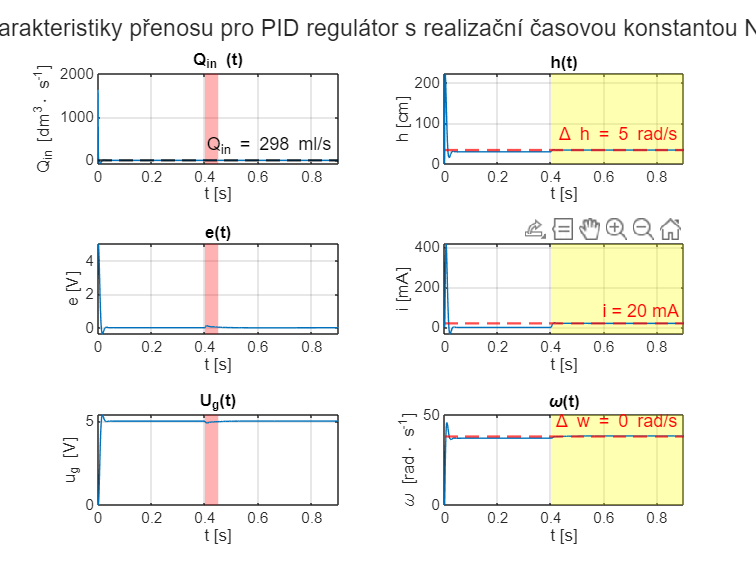

nexttile;
plot(out_pid.w.Time, out_pid.w.Data);
xregion(0.4,4,'FaceColor', "y");
xlim([0 0.9]);
yline(38,'--r',sprintf('\\Delta w = 0 rad/s',38),'LineWidth',1.3);
grid on;
title('\omega(t)');
xlabel('t [s]');
ylabel('\omega [rad\cdot s^{-1}]');

### Export naměřených charakteristik do nového .pdf souboru

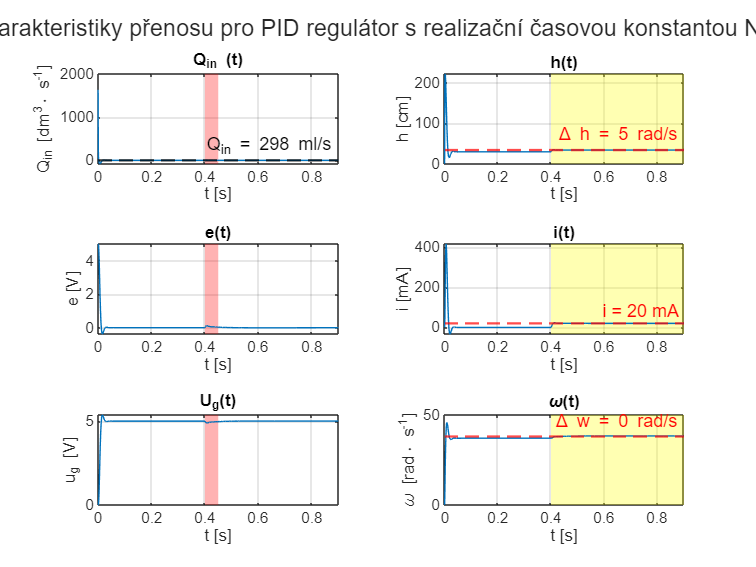

if isfile("FCHARPID100.pdf")
    delete("FCHARPID100.pdf");
end

exportgraphics(gcf, 'FCHARPID100.pdf', 'ContentType', 'vector');